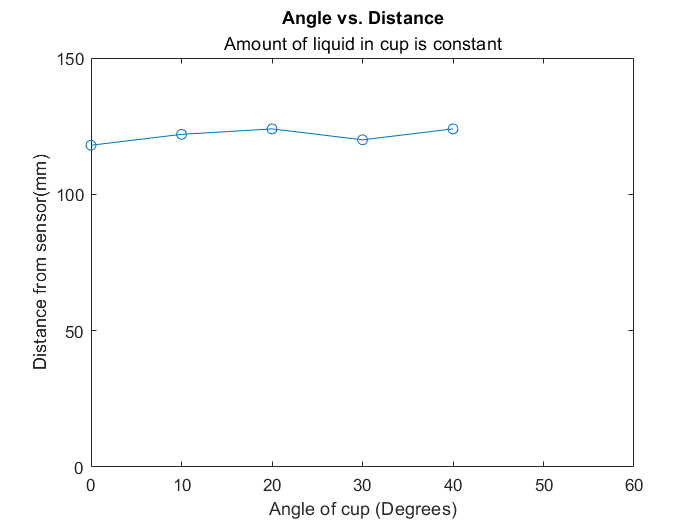

%There are two inches of liquid in the cup to begin with. This is a fixed
%varible.
angle = [0,10,20,30,40];
distance = [118,122,124,120,124];
figure(1);
plot(angle, distance, '-o')
hold on;
axis([0 60 0 150])
xlabel("Angle of cup (Degrees)")
ylabel("Distance from sensor(mm)")
title("Angle vs. Distance")
subtitle("Amount of liquid in cup is constant")

Calculate line of best fit

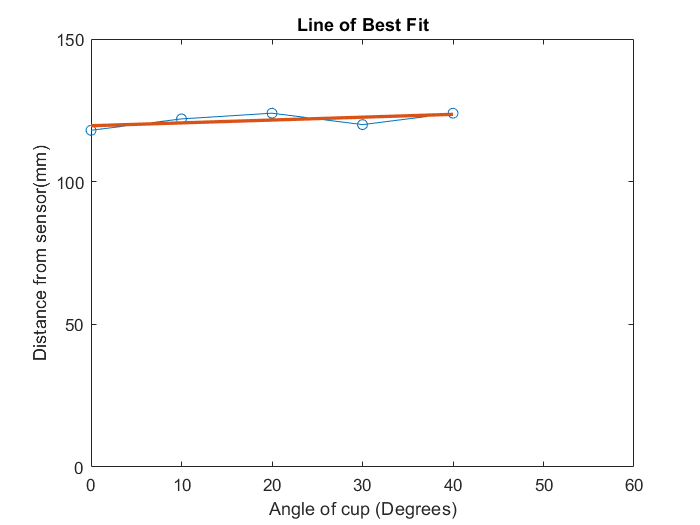

figure(2);
plot(angle, distance, '-o')
axis([0 60 0 150])
xlabel("Angle of cup (Degrees)")
ylabel("Distance from sensor(mm)")
title("Line of Best Fit")
hold on;
%Calculate line of best fit
coefficients = polyfit(angle, distance, 1);
xFit = linspace(min(angle),max(angle),10);
yFit = polyval(coefficients, xFit);
plot(xFit,yFit,'LineWidth',2);


%y=0.1x+119.6